clear all
close all
nameac = 'data_chirp.tmp/automatic_neddrone.mat'       ;
load(nameac)

tstart     =605               ;  
tend       =623.2               ;  
trange     = [tstart, tend]                         ;  %Interval of interest 


idx3       = find(ground_data.ROTORCRAFT_FP.timestamp>trange(1), 1, 'first')-1  ;  %Find lower bound index
idx4       = find(ground_data.ROTORCRAFT_FP.timestamp>trange(2), 1, 'first')-1  ;  %Find upper bound index
range2      = idx3 : idx4                           ;  %Useful range    

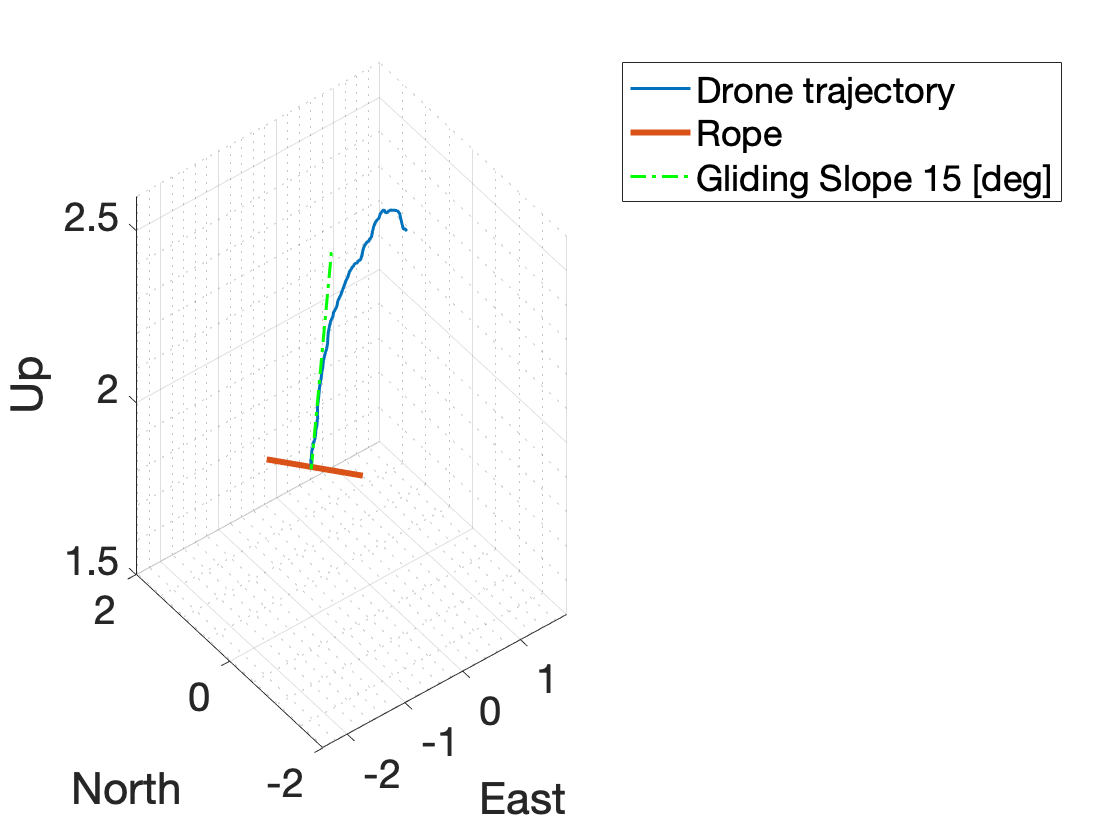

v_east   = ground_data.ROTORCRAFT_FP.veast_alt;
v_north  = ground_data.ROTORCRAFT_FP.vnorth_alt;
v_up     = ground_data.ROTORCRAFT_FP.vup_alt;

v_total = sqrt(v_east.^2+v_north.^2+v_up.^2);
s_north  = ground_data.ROTORCRAFT_FP.north_alt(range2);
s_east   = ground_data.ROTORCRAFT_FP.east_alt(range2);
s_up     = ground_data.ROTORCRAFT_FP.up_alt(range2);

s_north_c  = ground_data.ROTORCRAFT_FP.carrot_north_alt(range2);
s_east_c   = ground_data.ROTORCRAFT_FP.carrot_east_alt(range2);
s_up_c     = ground_data.ROTORCRAFT_FP.carrot_up_alt(range2);

time_gr  = ground_data.ROTORCRAFT_FP.timestamp(range2);

n =size(s_up,1);
rope_h =min(s_up);%2.23;
rope_up = ones(n,1)*rope_h;

one = [s_north(n-25) s_east(n-25)];%[-1.2 -0.6];
two = [s_north(n) s_east(n)];%[-1.9 -1.15]

m = (one(2)-two(2))/(one(1)-two(1));
m_p = -1/m;

rope_n_lim = [-0.8, -1.8];
step = (rope_n_lim(2)-rope_n_lim(1))/(n-1);
rope_north=(rope_n_lim(1):step:rope_n_lim(2)).';
rope_east = (m_p *(rope_north-two(1))+two(2)).';

slope = 15;


slope_n_lim = [-1.3, 2];
step = (slope_n_lim(2)-slope_n_lim(1))/(n-1);
slope_north = (slope_n_lim(1):step:slope_n_lim(2)).';
slope_east = (m*(slope_north-two(1))+two(2));
slope_NE = sqrt((slope_n_lim(1)-slope_n_lim(2))^2+(max(slope_east)-min(slope_east))^2);
slope_up_lim = [rope_h tan(deg2rad(slope))*slope_NE+rope_h];
step = (slope_up_lim(2)-slope_up_lim(1))/(n-1);
slope_up = slope_up_lim(1):step:slope_up_lim(2);

[x, y] = meshgrid(-2:0.1:2); % Generate x and y data
z = ones(size(x, 1))*rope_h; % Generate z data




figure(50)
clf
plot3(s_east, s_north, s_up,'LineWidth',1.5)
hold on
plot3(rope_east, rope_north,  rope_up,'LineWidth',3);
plot3(slope_east, slope_north, slope_up, '-.g','LineWidth',1.5)
%surf(x, y, z) % Plot the surface
ylabel('North')
xlabel('East')
zlabel('Up')
zlim([1.5 2.6])
%plot3(s_north_c, s_east_c, s_up_c)
set(gca,'fontsize',20)
grid minor
grid on
legend('Drone trajectory', 'Rope', 'Gliding Slope 15 [deg]')

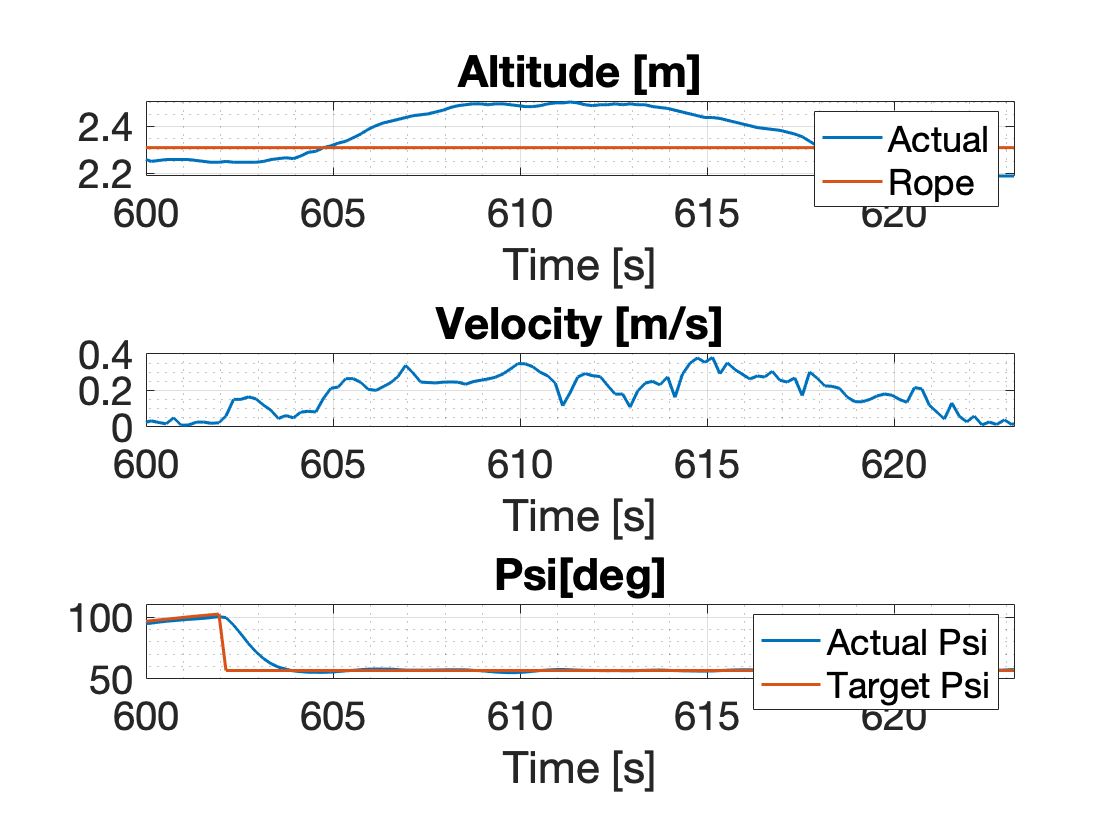

linesize = 1.5;

figure(3)
clf
ax1 = subplot(3,1,1);
plot(ground_data.ROTORCRAFT_FP.timestamp, ground_data.ROTORCRAFT_FP.up_alt,'LineWidth',linesize)
hold on
plot(ground_data.ROTORCRAFT_FP.timestamp, ground_data.ROTORCRAFT_FP.carrot_up_alt,'LineWidth',linesize)
title('Altitude [m]');
xlabel('Time [s]');
set(gca,'fontsize',20)
grid minor
grid on
legend('Actual', 'Rope')
%ylim([-10 10]);

ax2 = subplot(3,1,2);
plot(ground_data.ROTORCRAFT_FP.timestamp, v_total,'LineWidth',linesize)
title('Velocity [m/s]');
xlabel('Time [s]');
set(gca,'fontsize',20)
grid minor
grid on
%ylim([-10 10]);

ax3 = subplot(3,1,3);
plot(ground_data.ROTORCRAFT_FP.timestamp, ground_data.ROTORCRAFT_FP.psi_alt,'LineWidth',linesize)
hold on
plot(ground_data.ROTORCRAFT_FP.timestamp, ground_data.ROTORCRAFT_FP.carrot_psi_alt,'LineWidth',linesize)

title('Psi[deg]')
xlabel('Time [s]');
set(gca,'fontsize',20)
grid minor
grid on
ylim([50 110]);
legend('Actual Psi', 'Target Psi')


linkaxes([ax1,ax2,ax3],'x')
xlim([tstart-5 tend])

Take off plots

tstart     =580               ;  
tend       =590               ;  
trange     = [tstart, tend]                         ;  %Interval of interest 


idx3       = find(ground_data.ROTORCRAFT_FP.timestamp>trange(1), 1, 'first')-1  ;  %Find lower bound index
idx4       = find(ground_data.ROTORCRAFT_FP.timestamp>trange(2), 1, 'first')-1  ;  %Find upper bound index
range2      = idx3 : idx4                           ;  %Useful range    


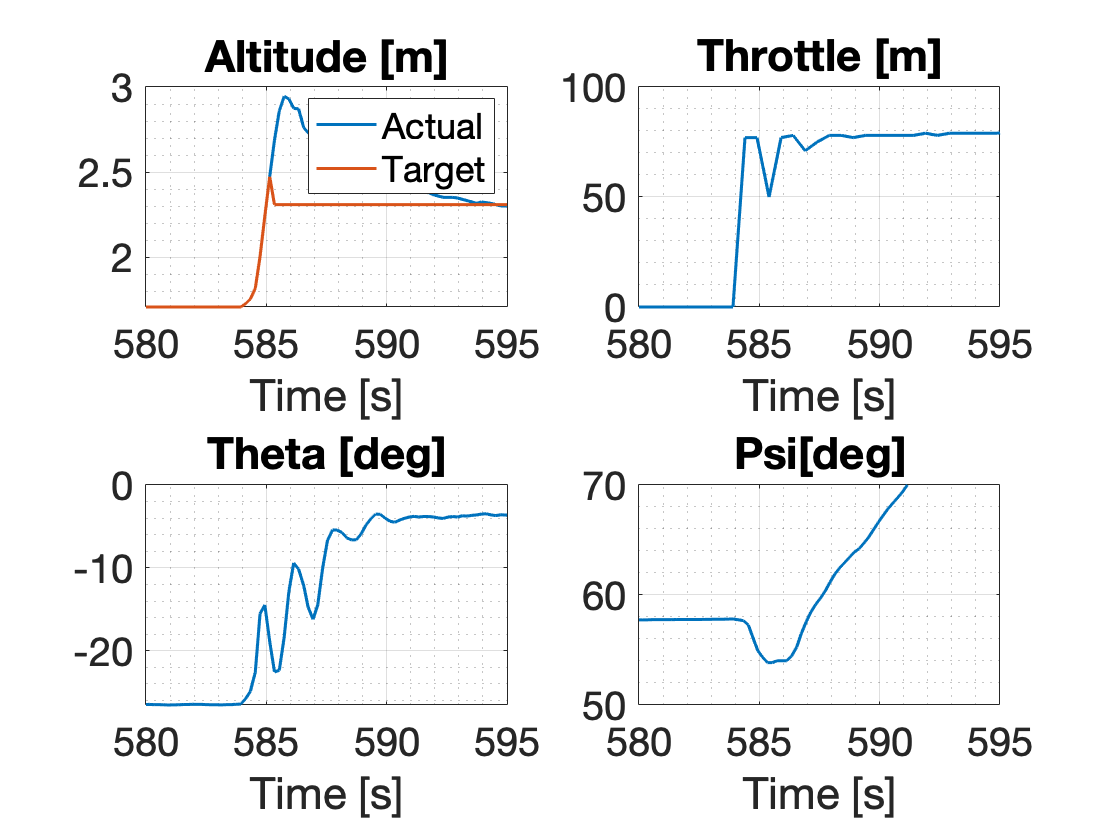

linesize = 1.5;

figure(4)
clf

ax1 = subplot(2,2,1);
plot(ground_data.ROTORCRAFT_FP.timestamp, ground_data.ROTORCRAFT_FP.up_alt,'LineWidth',linesize)
hold on
plot(ground_data.ROTORCRAFT_FP.timestamp, ground_data.ROTORCRAFT_FP.carrot_up_alt,'LineWidth',linesize)
title('Altitude [m]');
xlabel('Time [s]');
set(gca,'fontsize',20)
grid minor
grid on
legend('Actual','Target')
%ylim([-10 10]);

ax2 = subplot(2,2,2);
%plot(ground_data.ROTORCRAFT_FP.timestamp, ground_data.ROTORCRAFT_FP.thrust,'LineWidth',linesize)
plot(ground_data.ENERGY.timestamp, ground_data.ENERGY.throttle,'LineWidth',linesize)
title('Throttle [m]');
xlabel('Time [s]');
set(gca,'fontsize',20)
grid minor
grid on
ylim([0 100]);

ax4 = subplot(2,2,3);
plot(ground_data.ROTORCRAFT_FP.timestamp, ground_data.ROTORCRAFT_FP.theta_alt,'LineWidth',linesize)
title('Theta [deg]');
xlabel('Time [s]');
set(gca,'fontsize',20)
grid minor
grid on
%ylim([-10 10]);


ax5 = subplot(2,2,4);
plot(ground_data.ROTORCRAFT_FP.timestamp, ground_data.ROTORCRAFT_FP.psi_alt,'LineWidth',linesize)
%hold on
%plot(ground_data.ROTORCRAFT_FP.timestamp, ground_data.ROTORCRAFT_FP.carrot_psi_alt,'LineWidth',linesize)

title('Psi[deg]')
xlabel('Time [s]');
set(gca,'fontsize',20)
grid minor
grid on
ylim([50 70]);


linkaxes([ax1,ax2, ax4, ax5],'x')
xlim([tstart tend])

vector landing plot

drone = [2,2,2];
rope  = [1,1,1];
rope_scale = 2;
rope_line = [cos(deg2rad(psi_r-90)), sin(deg2rad(psi_r-90)),0];
slope_gs = 45;
psi_r = 90;
s_I = rope-drone;
n_I = [cos(deg2rad(psi_r)), sin(deg2rad(psi_r)),0];
l_I = [-1*n_I(1)*cos(deg2rad(slope_gs)), -1*n_I(2)*cos(deg2rad(slope_gs)), -sin(deg2rad(slope_gs))]

l_I =    -0.0000   -0.7071   -0.7071


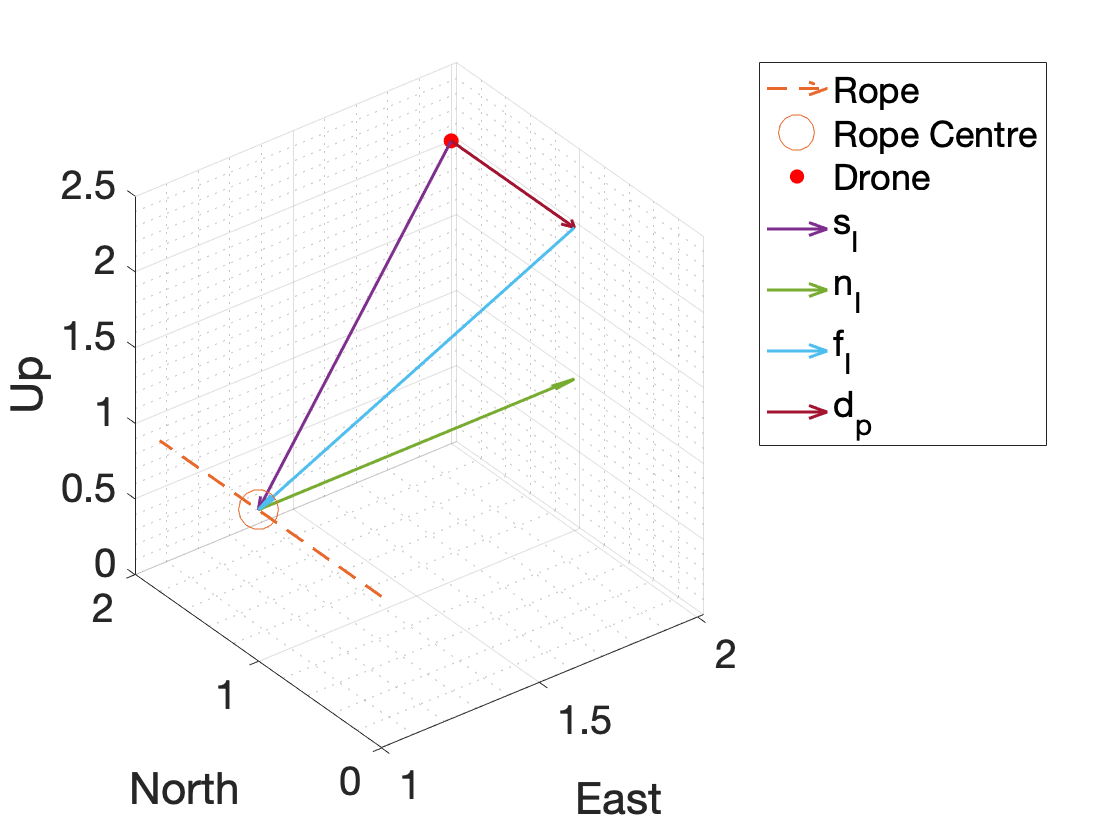

l_I_norm = sqrt(l_I(1)^2+l_I(2)^2+l_I(3)^2);
f_ratio = sum(s_I.*l_I)/l_I_norm^2;
f_I = f_ratio*l_I;
d_p= s_I-f_I;

line_size=1.5;
figure(22)
clf

h3=quiver3(rope(2)-rope_line(2)*rope_scale/2,rope(1)-rope_line(1)*rope_scale/2,rope(3)-rope_line(3)*rope_scale/2, rope_line(2)*rope_scale,rope_line(1)*rope_scale, rope_line(3)*rope_scale,'LineStyle','--','ShowArrowHead','off','LineWidth',linesize,'color',[0.9100    0.4100    0.1700]);
hold on
h2=plot3(rope(2),rope(1),rope(3),'o','MarkerSize',20,'color',[0.9100    0.4100    0.1700]);
h4=plot3(drone(1),drone(2),drone(3),'.r','MarkerSize',20);
h1=quiver3(drone(2),drone(1),drone(3),s_I(2),s_I(1),s_I(3),'AutoScale','off','LineWidth',linesize);
h5=quiver3(rope(2),rope(1),rope(3), n_I(2),n_I(1),n_I(3),'AutoScale','off','LineWidth',linesize);
%h6=quiver3(rope(2)-l_I(2),rope(1)-l_I(1),rope(3)-l_I(3), l_I(2),l_I(1),l_I(3),'AutoScale','off','LineWidth',linesize);
h7=quiver3(rope(2)-f_I(2),rope(1)-f_I(1),rope(3)-f_I(3),f_I(2),f_I(1),f_I(3),'AutoScale','off','LineWidth',linesize);
h8=quiver3(drone(1),drone(2),drone(3),d_p(2),d_p(1),d_p(3),'AutoScale','off','LineWidth',linesize);
zlim([0,2.5])
set(gca,'fontsize',20)
grid minor
grid on
ylabel('North')
xlabel('East')
zlabel('Up')
legend('Rope','Rope Centre','Drone','s_I','n_I','f_I','d_p')